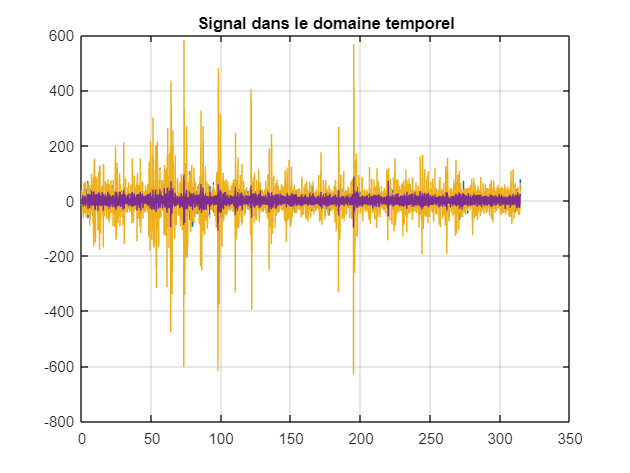

%% suppression de bruit, mouvements oculaires et signaux musculaires %%

eeg_data = csvread("data/Essai_1704_Test2.csv",1,0);
eeg_data1 = eeg_data(:,[1:8]); %toutes les électrodes
eeg_data2 = eeg_data(:,[1:4]); %électrodes 1,2,3,4

Fe = 250;
N = length(eeg_data2);
t = [0:N-1]/Fe;

figure(1)
plot(t,eeg_data2),grid
title('Signal dans le domaine temporel')

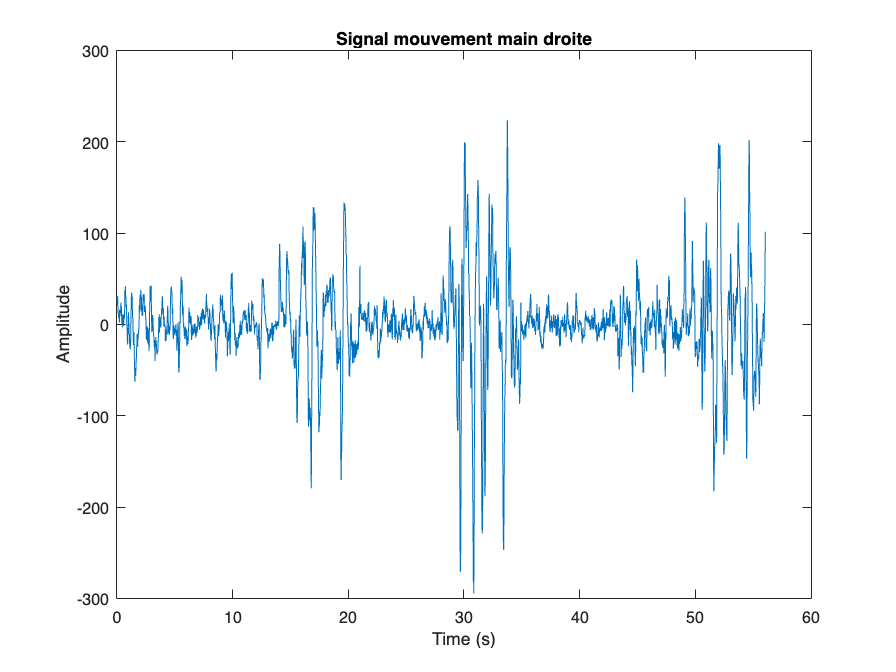

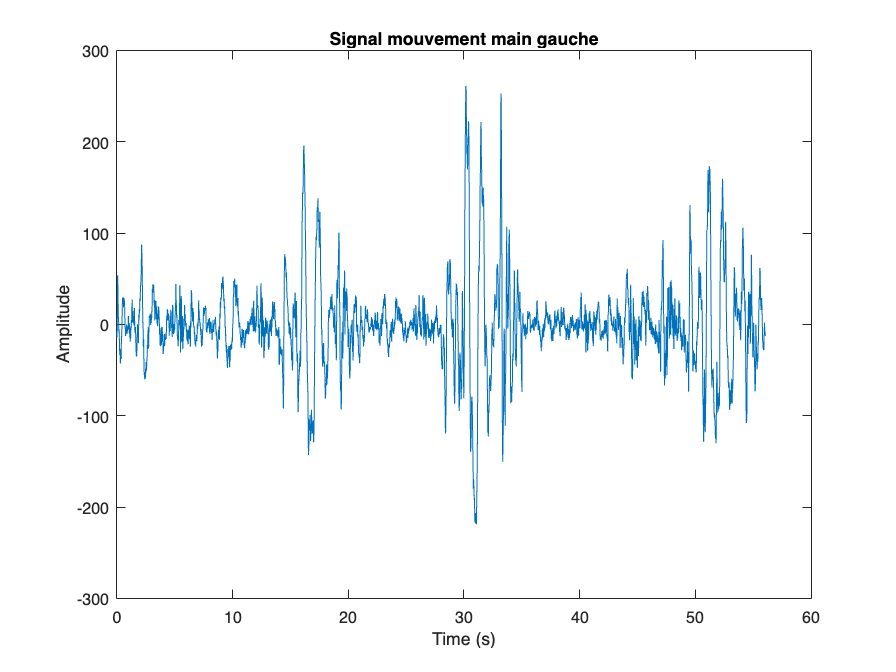

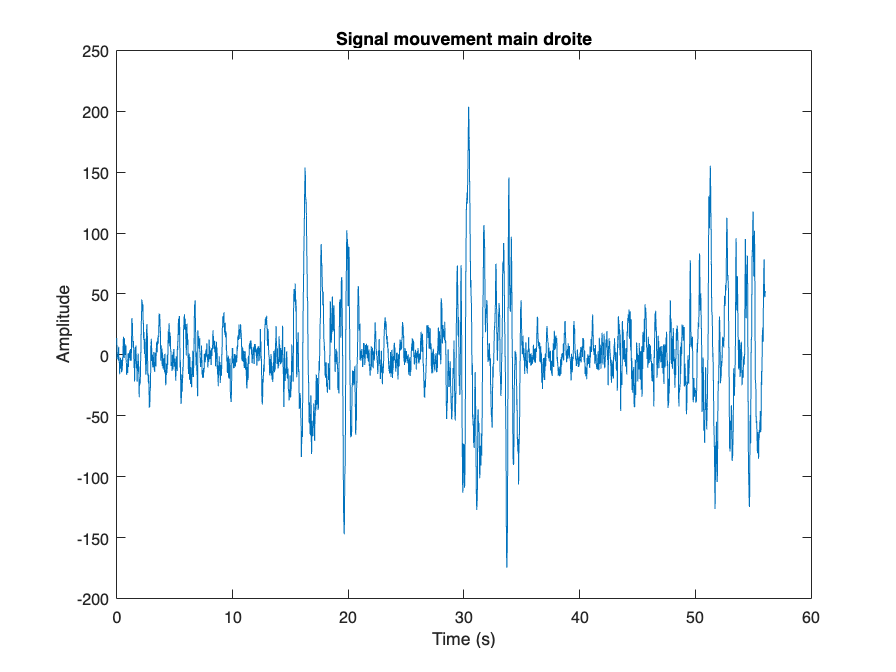

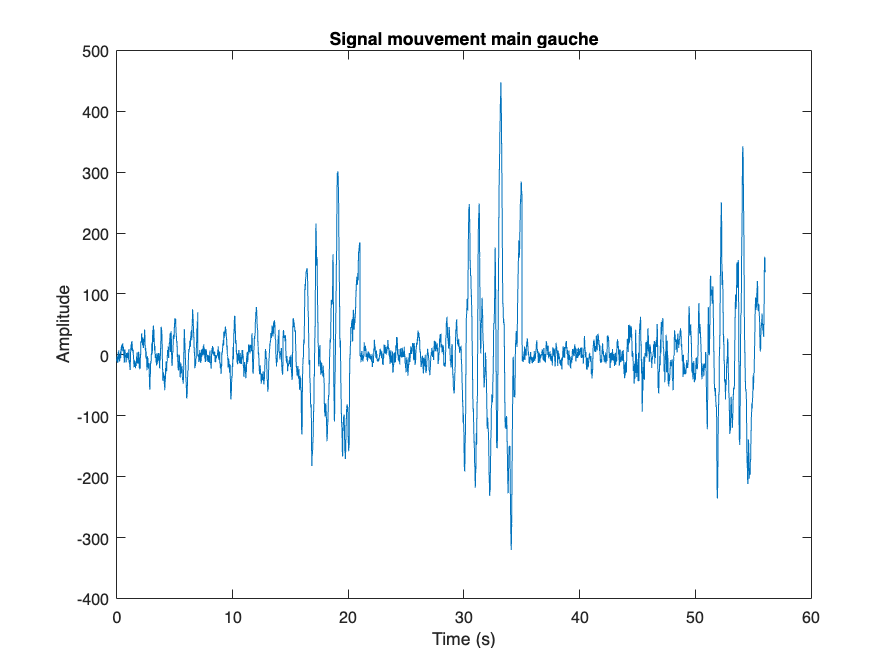

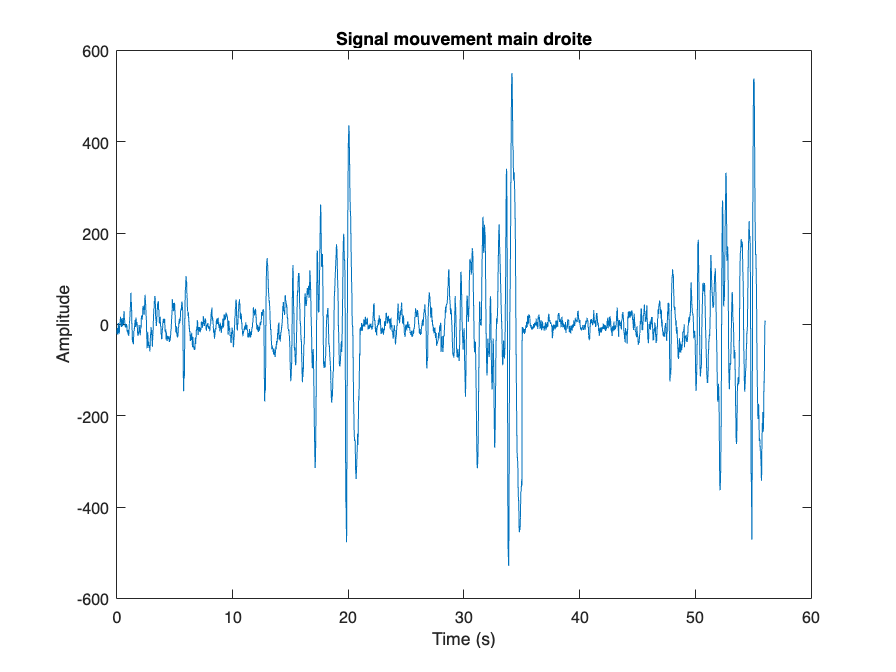

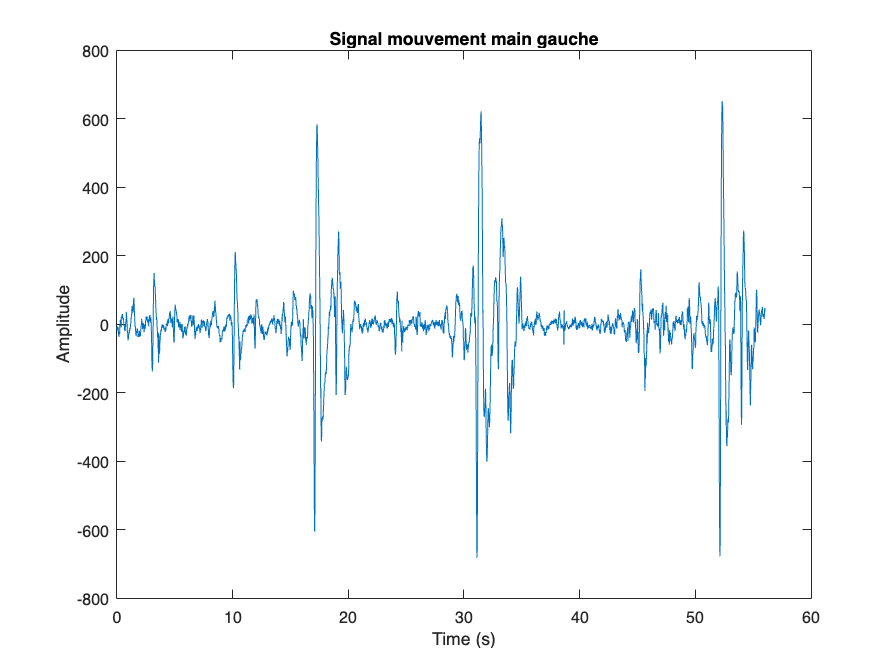

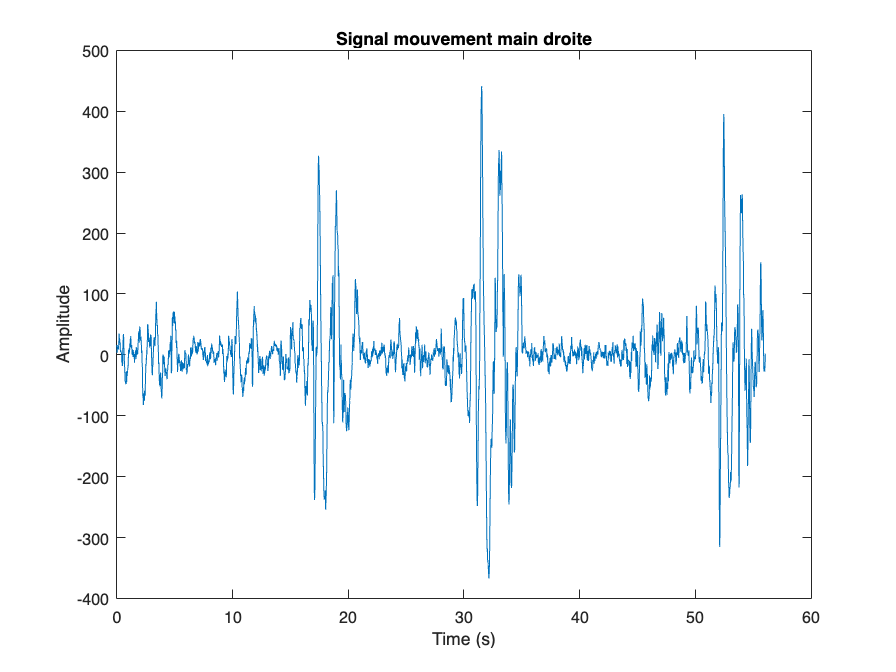

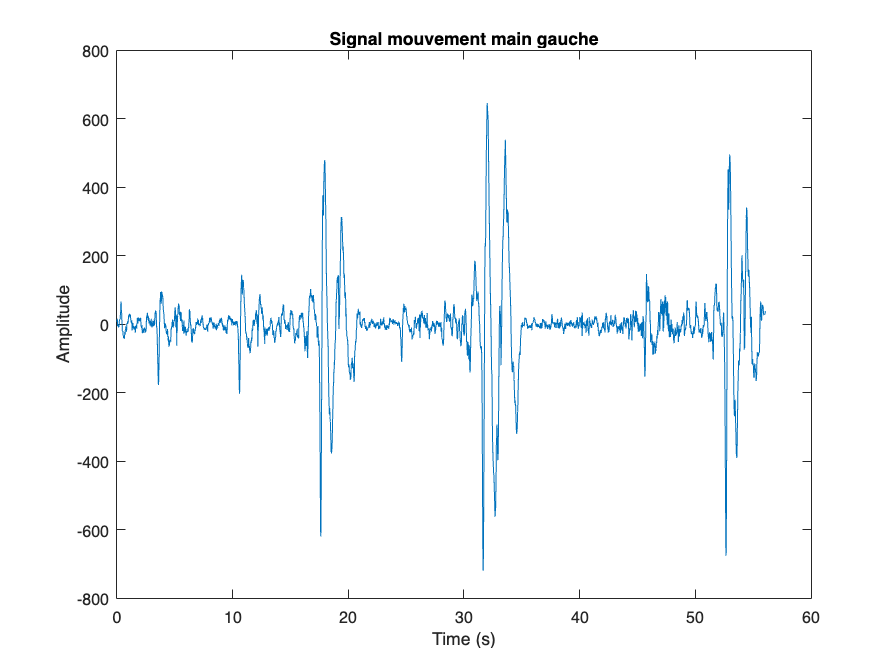

clear all
data = readmatrix("data/Essai_1704_Test2.csv");
data = data(:,1:8);
fs = 250; %fréquence d'échantillonnage
fc1 = 12;
fc2 = 35;
N = 75000;
decompte = 5*250;
nn = N/25;
ii = 0;
time = linspace(0,7*8);

for i = 0:24
    startIndexCroix = int32(decompte + nn*i);
    endIndexCroix = int32(decompte + nn*i + 5*250);
    startIndexSignal = int32(endIndexCroix);
    endIndexSignal = int32(startIndexSignal + 7*250);

    croix = data(startIndexCroix:endIndexCroix,:);
    if mod(i,2) == 0
        label = 'Droite';
        mouvement = data(startIndexSignal:endIndexSignal, :);
        droite = [mouvement(:,1);...
            mouvement(:,2);...
            mouvement(:,3);...
            mouvement(:,4);...
            mouvement(:,5);...
            mouvement(:,6);...
            mouvement(:,7);...
            mouvement(:,8)];
        duration = length(droite) / fs;
        time = linspace(0, duration, length(droite));
        figure;
        plot(time,droite)
        title('Signal mouvement main droite');xlabel('Time (s)');ylabel('Amplitude');
    else
        label = 'Gauche';
        mouvement = data(startIndexSignal:endIndexSignal, :);
        gauche = [mouvement(:,1);...
            mouvement(:,2);...
            mouvement(:,3);...
            mouvement(:,4);...
            mouvement(:,5);...
            mouvement(:,6);...
            mouvement(:,7);...
            mouvement(:,8)];
        duration = length(gauche) / fs;
        time = linspace(0, duration, length(gauche));
        figure;
        plot(time,gauche)
        title('Signal mouvement main gauche');xlabel('Time (s)');ylabel('Amplitude');
    end
end

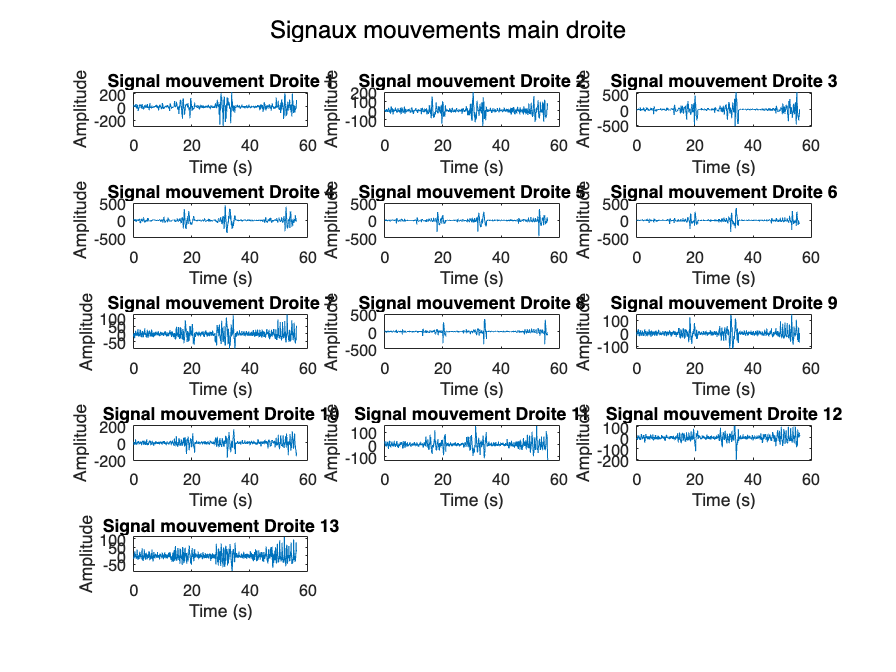

clear all
data = readmatrix("data/Essai_1704_Test2.csv");
data = data(:,1:8);
fs = 250; %fréquence d'échantillonnage
fc1 = 12;
fc2 = 35;
N = 75000;
decompte = 5*250;
nn = N/25;
ii = 0;

% Création de la figure pour les mouvements de la main droite
figure;
sgtitle('Signaux mouvements main droite avant filtrage');
for i = 0:24
    startIndexCroix = int32(decompte + nn*i);
    endIndexCroix = int32(decompte + nn*i + 5*250);
    startIndexSignal = int32(endIndexCroix);
    endIndexSignal = int32(startIndexSignal + 7*250);

    croix = data(startIndexCroix:endIndexCroix,:);
    if mod(i,2) == 0
        label = 'Droite';
        mouvement = data(startIndexSignal:endIndexSignal, :);
        droite = [mouvement(:,1);...
            mouvement(:,2);...
            mouvement(:,3);...
            mouvement(:,4);...
            mouvement(:,5);...
            mouvement(:,6);...
            mouvement(:,7);...
            mouvement(:,8)];
        duration = length(droite) / fs;
        time = linspace(0, duration, length(droite));
        subplot(5,3,i/2+1);
        plot(time,droite)
        title(sprintf('Signal mouvement %s %d', label, i/2+1));
        xlabel('Time (s)');ylabel('Amplitude');
    end
end

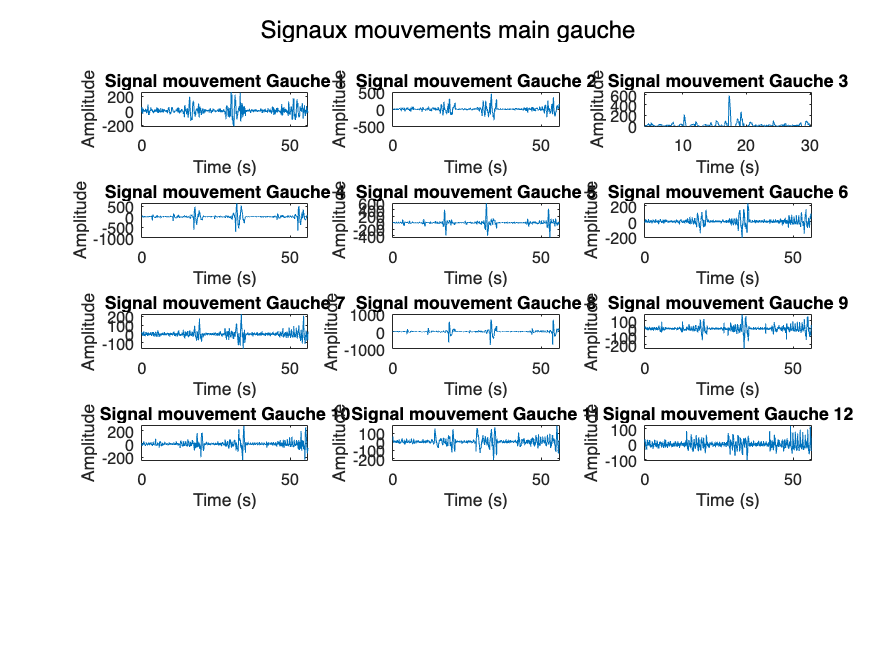


% Création de la figure pour les mouvements de la main gauche
figure;
sgtitle('Signaux mouvements main gauche avant filtrage');
for i = 0:24
    startIndexCroix = int32(decompte + nn*i);
    endIndexCroix = int32(decompte + nn*i + 5*250);
    startIndexSignal = int32(endIndexCroix);
    endIndexSignal = int32(startIndexSignal + 7*250);

    croix = data(startIndexCroix:endIndexCroix,:);
    if mod(i,2) ~= 0
        label = 'Gauche';
        mouvement = data(startIndexSignal:endIndexSignal, :);
        gauche = [mouvement(:,1);...
            mouvement(:,2);...
            mouvement(:,3);...
            mouvement(:,4);...
            mouvement(:,5);...
            mouvement(:,6);...
            mouvement(:,7);...
            mouvement(:,8)];
        duration = length(gauche) / fs;
        time = linspace(0, duration, length(gauche));
        subplot(5,3,(i-1)/2+1);
        plot(time,gauche)
        title(sprintf('Signal mouvement %s %d', label, (i-1)/2+1));
        xlabel('Time (s)');ylabel('Amplitude');
    end
end

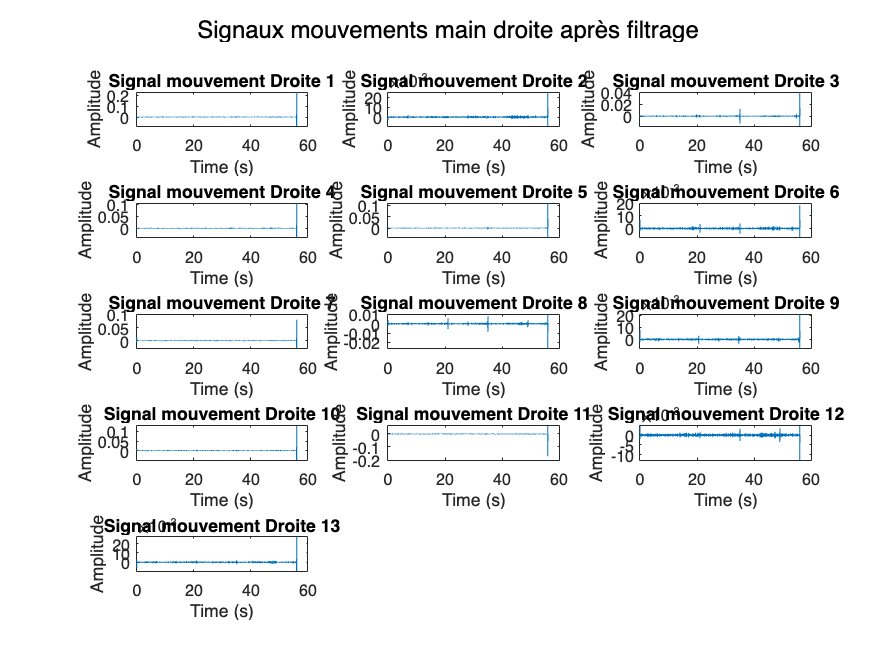

clear all
data = readmatrix("data/Essai_1704_Test2.csv");
data = data(:,1:8);
fs = 250; %fréquence d'échantillonnage
fc1 = 12;
fc2 = 35;
N = 75000;
decompte = 5*250;
nn = N/25;
ii = 0;

% Création de la figure pour les mouvements de la main droite
figure;
sgtitle('Signaux mouvements main droite après filtrage');
for i = 0:24
    startIndexCroix = int32(decompte + nn*i);
    endIndexCroix = int32(decompte + nn*i + 5*250);
    startIndexSignal = int32(endIndexCroix);
    endIndexSignal = int32(startIndexSignal + 7*250);

    croix = data(startIndexCroix:endIndexCroix,:);
    if mod(i,2) == 0
        label = 'Droite';
        mouvement = data(startIndexSignal:endIndexSignal, :);
        droite = [mouvement(:,1);...
            mouvement(:,2);...
            mouvement(:,3);...
            mouvement(:,4);...
            mouvement(:,5);...
            mouvement(:,6);...
            mouvement(:,7);...
            mouvement(:,8)];
        [b,a] = butter(4,fc1/(fs/2),"low"); %filtre passe-bas (supprimer bruit à haute fréquence)
        eeg_data_filtered = filtfilt(b,a,droite); % appliquer filtre aux données EEG
        
        [b,a] = butter(4,fc2/(fs/2),"high"); %filtre passe-haut (supprimer bruit à basse fréquence)
        eeg_data_filtered = filtfilt(b,a, eeg_data_filtered);
        duration = length(eeg_data_filtered) / fs;
        time = linspace(0, duration, length(eeg_data_filtered));
        subplot(5,3,i/2+1);
        plot(time,eeg_data_filtered)
        title(sprintf('Signal mouvement %s %d', label, i/2+1));
        xlabel('Time (s)');ylabel('Amplitude');
    end
end

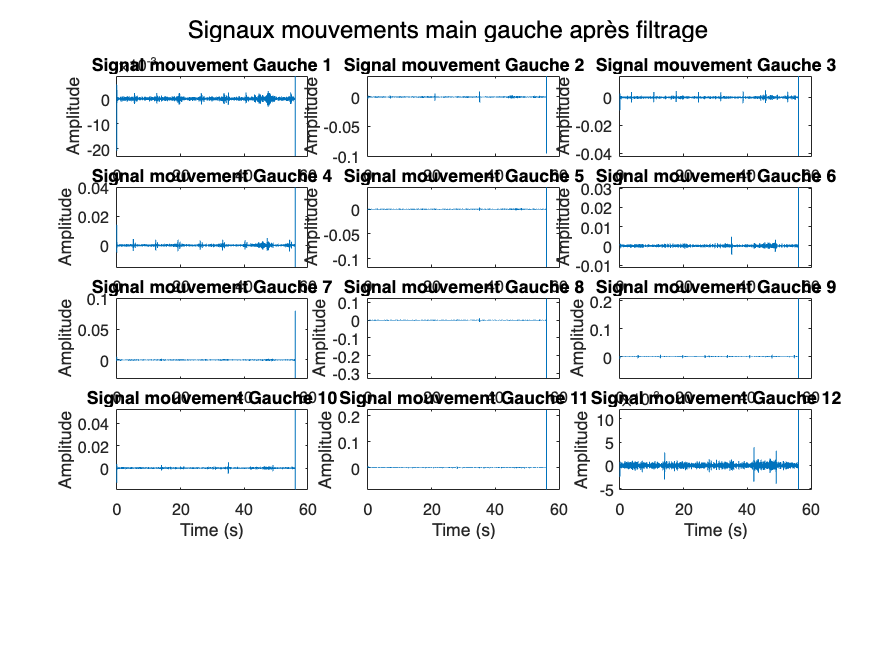


% Création de la figure pour les mouvements de la main gauche
figure;
sgtitle('Signaux mouvements main gauche après filtrage');
for i = 0:24
    startIndexCroix = int32(decompte + nn*i);
    endIndexCroix = int32(decompte + nn*i + 5*250);
    startIndexSignal = int32(endIndexCroix);
    endIndexSignal = int32(startIndexSignal + 7*250);

    croix = data(startIndexCroix:endIndexCroix,:);
    if mod(i,2) ~= 0
        label = 'Gauche';
        mouvement = data(startIndexSignal:endIndexSignal, :);
        gauche = [mouvement(:,1);...
            mouvement(:,2);...
            mouvement(:,3);...
            mouvement(:,4);...
            mouvement(:,5);...
            mouvement(:,6);...
            mouvement(:,7);...
            mouvement(:,8)];
        [b,a] = butter(4,fc1/(fs/2),"low"); %filtre passe-bas (supprimer bruit à haute fréquence)
        eeg_data_filtered = filtfilt(b,a,gauche); % appliquer filtre aux données EEG
        
        [b,a] = butter(4,fc2/(fs/2),"high"); %filtre passe-haut (supprimer bruit à basse fréquence)
        eeg_data_filtered = filtfilt(b,a, eeg_data_filtered);
        duration = length(eeg_data_filtered) / fs;
        time = linspace(0, duration, length(eeg_data_filtered));
        subplot(5,3,i/2+1);
        plot(time,eeg_data_filtered)
        title(sprintf('Signal mouvement %s %d', label, (i-1)/2+1));
        xlabel('Time (s)');ylabel('Amplitude');
    end
end